load('playpensample.mat');
theta = theta(r>0);
r = r(r>0);
theta = theta(r<5);
r = r(r<5);
[x,y] = pol2cart(deg2rad(theta),r);
xOrig = x;
yOrig = y;



starts = [];
vects = [];

while(length(x)>1)
    %plot(x,y,'bs')
    figure
    [bestStart,bestVect,ptsOnLine] = findLine(x, y, .05, 100);
    starts = [starts bestStart];
    vects = [vects bestVect];
    x = x(~ptsOnLine);
    y = y(~ptsOnLine);  
end

   290



   251



   187



   148



   114



    91



    73



    60



    40



    26



    19



    14



     9



     5



     2



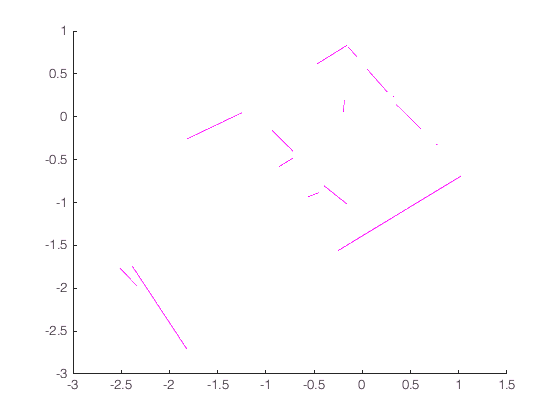

clf
%plot(xOrig,yOrig, 'ks');
hold on
t = linspace(0, 1);
for i = 1:size(vects,2)
    plot(t*vects(1,i)+starts(1,i),t*vects(2,i)+starts(2,i),'m');
end

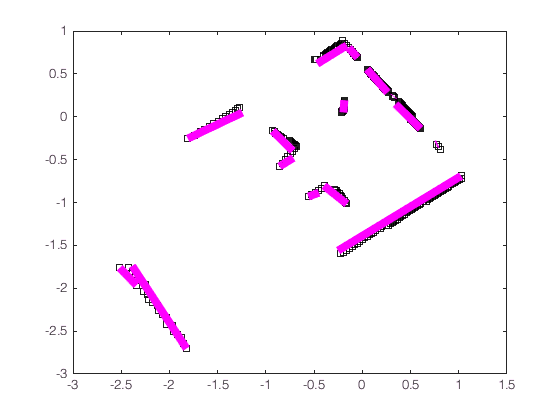

figure
clf
plot(xOrig,yOrig, 'ks');
hold on
t = linspace(0, 1);
for i = 1:size(vects,2)
    plot(t*vects(1,i)+starts(1,i),t*vects(2,i)+starts(2,i),'m','LineWidth', 6);
end

function res = dist2line(x, y, start, vect)
    M = [x y];
    M = M - start';
    normal = [-vect(2) ; vect(1)];
    normal = normal/norm(normal);
    res = abs(M * normal);
end
function res = distOnLine(x, y, start, vect)
    M = [x y];
    M = M - start';
    projVect = vect/norm(vect);
    res = M * projVect;
end
function [bestStart,bestVect,ptsOnLine] = findLine(x, y, epsilon, nTries)
    nPoints = length(x);

    bestStart = [0; 0];
    bestVect = [0; 0];
    bestScore = -Inf;
    ptsOnLine = [];
    
    for succ = 1:nTries
        i=0;
        j=0;
        while(i==j)
            i = randi(nPoints);
            j = randi(nPoints);
        end
        a = [x(i);y(i)];
        b = [x(j);y(j)];
        vect = b-a;
        dist = dist2line(x,y,a,vect);
        score = sum(dist < epsilon);
        if(score > bestScore)
            bestScore = score;
            bestStart = a;
            bestVect = vect;
            ptsOnLine = dist < epsilon;
        end
    end
    ptsOnLine = removeGaps(x, y, ptsOnLine, bestStart, bestVect, 2);
    [bestStart, bestVect]= normalizeLine(x, y, ptsOnLine, bestStart, bestVect);
end
function pts = removeGaps(x, y, ptsOnLine, start, vect, epsilon)
    xsOnLine = x(ptsOnLine);
    ysOnLine = y(ptsOnLine); 
    ts = distOnLine(xsOnLine, ysOnLine, start, vect/norm(vect));
    [tsSorted,indicies] = sort(ts);
    diffs = diff(tsSorted);
    meanDiff = mean(diffs);
    breaks = [0; find(diffs>meanDiff*epsilon); length(ts)];
    lengths = diff(breaks);
    [~,maxSegment] = max(lengths);
    indiciesOnLine = breaks(maxSegment)+1:breaks(maxSegment+1);
    localIndicies = indicies(indiciesOnLine);
    
    L = [xsOnLine(localIndicies) ysOnLine(localIndicies)];
    G = [x y];
    
    pts = ismember(G, L, 'rows');
end
function [start, vect]= normalizeLine(x, y, ptsOnLine, bestStart, bestVect)
    ts = distOnLine(x(ptsOnLine), y(ptsOnLine), bestStart, bestVect);
    
    len = max(ts)-min(ts);
    [~,startIndex] = min(ts);
    
    xsOnLine = x(ptsOnLine);
    ysOnLine = y(ptsOnLine);
    start = [xsOnLine(startIndex); ysOnLine(startIndex)];
    vect = len*bestVect/norm(bestVect);
end